# Lab 1 - September 8, 2023

## Starting a new piece of code!

It's important that your code is clean, replicable, and readable by you and others. At the top of a script or a function file, we should always write a few comments about who wrote the script, when they did it, and why. It's also important to clean your workspace up. Use the Matlab command "clear all" to clear all previously existing variables, and "close all" to close all existing figures. Your results should be reproducable from a completely blank starting point, otherwise you might have one result one day, and a different one the next day. Yikes!

% This is the file for MathTools lab #1. 
% Materials adapted over the years by Math Tools TA and instructors. 
% This exact tutorial was authored/updated by Marissa Fassold, Jordan Lei,
% and Srinidhi Venkatesan Kalavai for Math Tools 2022, 
% then adapted by Sarah Master and Eero Simoncelli for Math Tools 2023. 

clear all

## Importing data

Before we can import data, we need to make sure that the data is in a place Matlab can find it. We can ensure that this is the case either by making sure that the data is in Matlab's file path, or by specifying a path to the file when you load it.

Most well-organized directories of code do not have data sitting in the same directory as everything else. In fact, code directories should more or less be organized the same way you might organize a regular folder of files. The more readable/user-friendly, the better! In this case, we have a main home directory (where you are now), a "data" directory, and a "functions" directory.

First, let's start by making sure our directory for data exists, and look at what's in it. We are going to be working with a file called "data.mat," so let's make sure it's sitting in our data directory.

% You can run "pwd" in Matlab to see which directory you are in, and "ls"
% to see which files and folders are in that directory.

current_directory = pwd

current_directory = '/MATLAB Drive'

ls(current_directory) 

data  functions  Lab1_Matlab_Solutions_2022.mlx  Lab1_Matlab_Tutorial_2022.mlx	Lab1_Matlab_Tutorial_2023eps.mlx  Lab1_Matlab_Tutorial_2023.mlx  Lab1_Matlab_Tutorial_2023_v02.mlx  Lab2_Matlab_Tutorial_2022.mlx




% You can also use "ls" to look in directories other than the one you're in
ls('data/')

data.mat



Now that we can see that "data.mat" is in fact in our data folder, let's make sure the data folder is added to the path. The Matlab "path" is the places which it will search *first* for files of the specified name. You can (and most likely will) have files named the same way (across Math Tools assignments, for example), so specifying which directories are most relevant to the code at hand is key. You can use a command to add folders to your path. Use the command addpath(genpath('my folder name')) to add a folder and all of its subfolders to your file path. You can also specify a file path when loading a file (e.g. load('C:\Users\user\Documents\MATLAB\data.mat')) and thereby avoid any potential issues from adding too much to the path.

Matlab data files contain variables. You can import these variables directly into the workspace by using the load function:

addpath('data/')
load('data.mat'); %loads a data file within MATLAB's file path

Try to import the data file provided with the lab.

One of the first things you should do when you are handed a piece of data is to look at its format. You can determine the type by checking the class of the variable.

class(data)

ans = 'struct'

dataStruct is a variable of type 'struct'. Structures can be accessed using the syntax structname.VariableName. You can use the function **size** to look at the shape of the variable 'data' and its elements. How big is it? What does it contain?

size(data) 

ans =      1     1


size(data.x)

ans =      1    10


size(data.y)

ans =      1    10


This data is two vectors. One is the x value of a series, and the other a y. You can plug them into the "plot" variable to see how they relate to one another.

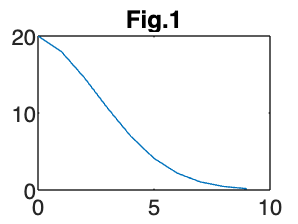

figure
plot(data.x,data.y)
title('Fig.1')

Hmm! What an interesting function. I wonder what it corresponds to?

## Conditionals

Conditional statements or "if" statements allow you to check if the conditions of a statement are met (For e.g. vector_length == 1 will return true (1) if the length of a vector is equal to 1, and return false (0) if the length is not 1). "if" statements are essentially a flow-chart for the computer. If the conditions of the statment are met, then the computer performs a specified action or calculation. If they are not met, the computer performs a different action, or no action. The syntax for "if" statements are:

if (condition)

    action

elseif (condition)

    action

else

    action

end

The computer computes each conditional in order. The last else will only be executed only if all the above statements are false. An else statement is also not required! If you do not want to execute anything if the conditional is false, you can end the if statement without the else statement.

The condition in the if statement can be any boolean expression that returns a true or false value. The common boolean expressions are: a==b, a~=b, a<b, a>b, a<=b, a>=b. These operations will work for scalar variables as well as vectors, matrices and even character arrays and strings.

You can also compare vectors and matrices with the function **isequal(v1,v2)**. For strings, try strcmp(string1,string2)

You can make complex logical statements by combining inequalities.

a==b && b==c checks that both conditions are true

a==b || b==c checks that either of the conditions are true.

Note:  == is really only reliable for boolean or integer values.  Comparing floating-point numbers can be problematic, because they are rounded off during computations.  For example, calling log(exp(x)) should return x, but because of small numerical roundoff errors in the two functions, comparing with ==  only succeeds about 50% of the time!

N=10000; 
x= rand(N,1);   % make a vector of N random values to test
y=log(exp(x));  % compute y= log(exp(x))
sum(y==x)/N     % for what fraction of these values is y==x?

ans = 0.4795

Note: && and || will only execute the right hand expression if the result of the computation is not clear from the left hand expression. They will also only operate on scalars. To compare element-wise on vectors, or to execute both right hand and left hand expressions, you can use & or | .

Let's try using conditionals! Write a piece of code to "flip a coin". Display "heads" or "tails" depending on the result (use disp() or fprintf()). Assume that the coin is fair, that is, the probability of a heads or a tails is 50%. 

Hint: You can use a random number generator to draw random numbers from a uniform distribution and assign 50% of the possible numbers to heads and the other 50% to tails.

% YOUR CODE HERE %

## Loops

Iteration is extremely valuable computational tool! It is the repetition of an action until a condition is met. In Matlab, the two main forms of iteration are "for" loops and "while" loops. The main difference between the two types of loops is that "for" loops repeat actions a set number of times, whereas "while" loops iterate until a condition is met.

For e.g.

v1 = linspace(1,50,10);
numIterations = 10;
for index = 1:numIterations %loop over these values
    % the variable you loop over will often be a list of sequential 
    % integers, as this makes indexing convenient
    disp(v1(index))
end

     1

    6.4444

   11.8889

   17.3333

   22.7778

   28.2222

   33.6667

   39.1111

   44.5556

    50



While e.g.

index = 1;
while index <= 10 %conditional checking if the program should exit the loop
    disp(v1(index)) %action to be taken
    index = index + 1; % you have to change the value referenced in the conditional
    % in the body of the loop or the while loop will run infinitely. To
    % quit out of the process, use ctrl + c (windows) or command + . (mac)
end

     1

    6.4444

   11.8889

   17.3333

   22.7778

   28.2222

   33.6667

   39.1111

   44.5556

    50



Let's try out loops! Write (a) a for loop to flip a coin 100 times and report the proportion that are heads and (b) a while loop to flip a coin until you have 50 heads, and report the proportion that are heads. 

Hint: For the for loop, create a variable called "pHeads" to act as a counter for the number of head flips. For the while loop, since you are iterating until a specific number of heads are acheived, keep track of the number of the flips to get to 50 heads instead.

% YOUR CODE HERE %

Tips: Matlab provides a few tools to visualize what your code is doing, which is especially useful for debugging and visualizing loops. You can add a break point(by clicking on the number on the left hand side) that will pause the execution of code (so you can check what is happening with your calculation). The commands 'break' and 'continue' can also be used to prematurely stop loops, or to skip certain iterations, for e.g.:

numIterations = 10;
for ii = 1:numIterations
    if (rem(ii,2)==0) % if ii is divisible by 2
        continue %skip to the next value
    end
    disp(v1(ii))
end

     1

   11.8889

   22.7778

   33.6667

   44.5556



You can also nest loops inside each other. Nested loops run fully on each iteration of the outside loop.

For e.g

for ii = 1:10 % loop runs 10 times
    for jj = 1:10 %this will run 10 X 10 times
        %code
    end
end

Tip: Remember to use different variables for each of your loops (I like to use ii, jj, kk, etc.). Additionally, if you plan to store the products of your loops (e.g., in a matrix), consider pre-allocating a data storage matrix/vector using nan(m,n) or zeros(m,n) where n and m are the sizes of your two loops.

## Functions!

Functions are used to 'package' a piece of code so that you can easily reproduce it. They are defined by specifying a set of input variables, a set of output variables, and a function name. In Matlab, the syntax for this is as follows:

function [output variables] = functionName (input variables)

    %compute output variables

end

You can define functions within a script, but they must be defined at the end of the script. Functions defined at the end of the script can be called within the script but not from the command window. In order to make user-defined functions work in the same way that built-in functions work, they must be saved as a separate .m file named after the function, and they should be in matlab's path (so it can find them!).  To check if your function is in matlab's path, use the "which" command.

Let's make a function!

Write a function myFlipStats to translate your "coin flip" loop into a function *coinFlip* that takes as input two values, nFlips and nTrials. nFlips is the number of flips of a coin to be made, repeating the process nTrials times. Have the function output a vector, pHeads, which contains the probability of getting a head calculated over each trial (Hint: the sum of the flips matrix divided by the length)

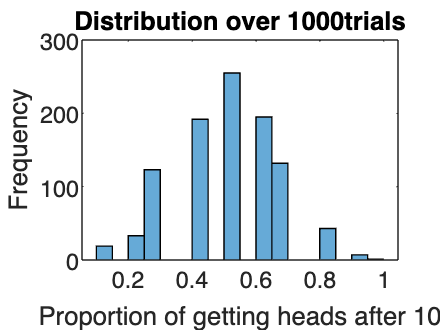

% CREATE A FUNCTION myFlipStats(nFlips, nTrials) BY
% USING THE "NEW" BUTTON ON THE UPPER LEFT, AND SELECTING FUNCTION 

% Once you have finished writing your function, run it below. Pay attention
% to how increasing nFlips increases how close your simulations get to
% producing the true probability of heads vs. tails, 50%. 
nFlips = 10;
N = 1000;
myFlipStats(nFlips, N);

figure;
histogram(pHeads)
xlabel(['Proportion of getting heads after ' num2str(nFlips) ' flips'])
title(['Distribution over ' num2str(N) ' trials'])
ylabel('Frequency')

Wait! There's a small problem with the code above! What is it? Does your histogram look correct? Why or why not?

Most likely, you're looking at a histogram describing the variable you previously named pHeads. Why is that? Well, it's because unless you explicitly ask for a function to return a variable to your script, when you make a new variable inside of a function, it stays inside of that function. All variables created in a function are accessible only within that function. This is called the "scope" of the function.

Fix the error in the above code and try it again!

## In-line functions versus function files

For simple functions (typically, one line), you can bypass the hassle of saving code in a file by defining them "inline":

myFunction = @(input_var) f(input_var)

For example, this function computes the square of the input variable:

sqr = @(x) x.^2;

If you want to write a function to be usable across multiple scripts, and even across multiple directories, you must save it as its own file. Save your function file for myFlipStats, then run the following commands to move it into the "functions" directory, to keep your code nice and clean.

% MATLAB can be used to move files around!
movefile('myFlipStats.m','functions/myFlipStats.m')

Error using movefile
No matching files named '/MATLAB Drive/myFlipStats.m' were found.

Okay, let's make sure myFlipStats.m is still usable.

nFlips=10;
N= 1000;
myFlipStats(nFlips, N)

Oops! Most likely you just got an error that you cannot run myFlipStats. Why is that? Because we haven't added the functions/ folder into the path yet.

% Add it to the path!
addpath('functions/')

% Check that it's readable and usable now with the "which" command. 
which myFlipStats.m

% Note: "which" is an especially useful command in the case that you have
% multiple copies of a function. It can tell you which one is encountered
% on the MATLAB path first.


## Using MATLAB to your advantage! (Or: speeding up loops)

Loops are very useful, and are often helpful for getting a conceptual understanding of a problem at hand (i.e. they can be used to sketch something out). But they are often inefficient, especially in Matlab. The more efficient (faster) thing to use, when possible, is matrix and vector operations (these are performed using highly-optimized loops internal to matlab). Let's go over a very simple example.

Let's return to the data we loaded up before:

disp(['X values in dataset: ' num2str(data.x)])
disp(['Y values in dataset: ' num2str(data.y)])

This is a simulated dataset which we created with "temporal discounting" in mind. Temporal discounting is the neuroeconomic phenomenon by which things seem less valuable to us the longer we have to wait to receive them. Most people would prefer to be given $20 today than in 2 weeks. You can model this by simulating an arbitrary decay function, using a "gamma" discounting parameter. First, let's simulate it using a loop.

% As in the original dataset, let's simulate 10 days of decay.
n_days = 10;

% Because x is our x-axis, which is just time, creating x is as simple as
% creating a vector of increasing integers with start point 0 and end point
% 9. (To make our simulations simple, the first day is going to be called Day 0.)
data.x = 0:9;

% We're going to repopulate data.y, so for now, let's re-initialize it so
% it's just an empty variable.
data.y = [];

% Set the discounting parameter, gamma:
gamma = 0.9;
% If you'd like to, you can play with this parameter, keeping it between 0
% and 1 (exclusive). Higher values of gamma will result in less temporal
% discounting.

% Set the initial value of the offer on day 0:
value = 20;

% Here is a loop which simulates temporal discounting over n_days days.
% The formula for temporal discounting is an exponential:
% value(t+1) = value(t) .* gamma^(t+1)
tic
for ii = 1:length(data.x)
    day = data.x(ii);
    % decrement the value by multiplying it by gamma^t
    value = value .* (gamma .^ day);
    data.y(ii) = value;
end
toc
% Note: the tic/toc command will print how long the code took to run from
% the "tic" command, to the "toc" command.

% Now plot your result to ensure it looks correct!
figure
plot(data.x,data.y)
xlabel('Day')
ylabel('Perceived value')

Now, go ahead and try doing the same thing, but WITHOUT using a loop!

tic
% % YOUR non-looping CODE HERE % %
toc

Then, check that your code is correct by plotitng the output:

% And plot!
figure
plot(data.x,data.y)
xlabel('Day')
ylabel('Perceived value')

## Exercises

### Exercise 1: Projections, change of coordinates, and angles.

**(a)** Write a function, "project" that takes two non-zero vectors, v and unit vector u as input and projects v onto u. Have the function output the length of the projected vector. Test the function on a few known cases.

**(b) **Write a function, "changeOfCoords" that takes two 2D vectors, v and u as input. Create a new "coordinate system" such that the vector u is one of the axes (you'll need to make this a unit vector, and generate the other axis, an orthogonal unit vector w).  Express the coordinates of v in the coordinate system defined by [u,w].   The function should return these coordinates, along with the matrix [u,w].  Test the function by showing that rescaling the new coordinate axes by these coordinate values and adding the produces the original vector.

**(c)** Write a function, "angleBetween" that takes two vectors, v and u, and calculates the angle between them.  Verify the answers on a few known cases.

Hint: the inverse cosine function acos() may prove useful.

### Exercise 2: Plotting a Unit Circle

A unit circle is a circle of radius 1, centered on the origin. When we get into matrix transformations, circles are often a nice way to visualize how a space can be transformed by a matrix. Let's think about how to create the unit circle. 

HINT: Use trigonometry! 

% YOUR CODE HERE %

% And plot!
plot([vectors(1,:)],[vectors(2,:)]);
title('Unit circle')

% Your plot should look like a perfect circle. If it doesn't, then try
% using "axis equal" to make sure your x and y axes are of the same length.

%P.S. Plot can be a slightly wonky/strange function to use. Try
%understanding why the above plot command plots the unit circle. Play
%around with giving plot different X/Y coordinates, and then giving it a
%vector to plot which originates at the origin.

### Exercise 3: Vectors as operators

Imagine there is a neuron with three dendrites. Each dendrite receives the same 8 inputs (has 8 synaptic terminals), but uses a different computation on those inputs to determine whether it should signal the cell to fire. Dendrite 1 acts as a simple averager. Dendrite 2 acts as windowed averager, only factoring in the last four inputs, Dendrite 3 acts as a component selector and only extracts the value of the last (eighth) dimension. The cell decides to fire is a majority of the dendrites surpass a threshold.

Create a function neuron() which takes a 8x1 input vector and a scalar threshold, and outputs the cell's decision to fire as a boolean value (0=no firing, 1 = firing). Randomly generate an input vector and test your function using an appropriate threshold value.

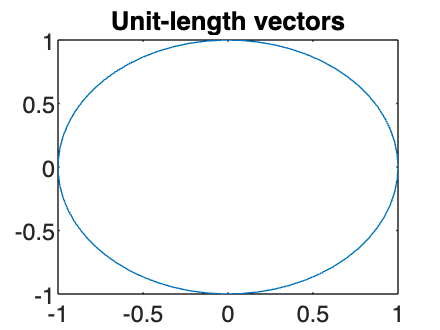

% function output = neurons(inputVec, threshold)
%     dendrite1 = []; %replace with an averager

%     dendrite2 = []; %replace with a windowed averager
%     dendrite3 = []; % replace with a component selector
%     
%     %Try to represent the action of the dendrite vectors on the input
%     %vector as a vector x matrix multiplication problem
%     
%     dendriteMatrix = [dendrite1,dendrite2,dendrite3];
%     response = 0; % REPLACE THIS CODE
%     
%     %Compare the response to the input threshold value and return the
%     %appropriate output
% 
% end

Now imagine that instead of those 8 inputs representing different synaptic terminals, they represent inputs over time. Write a function neuronOverTime, that takes as an input a threshold and a scalar T, a length of time. Randomly generate a vector of inputs with the length T, and use the 'neuron' function to generate the cell's response at each successive time point by calculating the reponse to subset of inputs, input(t:t+8). To measure the activity of the neuron at time t = 1, pad the input vector with zeros so that the first random number is input 8. Create a vector of output values (1s and 0s) and plot them as a "spike plot" using the function stem().